clear;
close all;

%% Data
m1=5.5; %kg
m2=4.75;
m3=3.9;
h=0.003; %s
L1=0.7; %m
L3=0.8; 
g=9.81; %m/s^2
Theta_CoM2=0.2; %kgm^2
q0=[0 0.15 0];
qd=[deg2rad(25) 0.4 deg2rad(25)];
qdp=[0; 0; 0];
qdpp=[0; 0; 0];

%% #1
syms theta_i a_i q1 q2 q3 
T=[cos(theta_i) -sin(theta_i) 0 a_i;
    sin(theta_i) cos(theta_i) 0 0;
    0 0 1 0;
    0 0 0 1];
a_1 = 0;
a_2 = q2;
a_3 = 0;
theta_1=q1+pi;
theta_2=0;
theta_3=-pi/2+q3;
T01=subs(T,[theta_i a_i],[theta_1 a_1]);
T12=subs(T,[theta_i a_i],[theta_2 a_2]);
T23=subs(T,[theta_i a_i],[theta_3 a_3]);
T02=T01*T12;
T03=T01*T12*T23;

syms t q_1(t) q_2(t) q_3(t) q_1p(t) q_2p(t) q_3p(t);
qt=[q_1(t), q_2(t),  q_3(t)];
dq=[diff(q_1(t),t),diff(q_2(t),t),diff(q_3(t),t)];
qpt=[q_1p(t) q_2p(t) q_3p(t)];
syms q_1pp(t) q_2pp(t) q_3pp(t);
ddq=[diff(q_1p(t),t),diff(q_2p(t),t),diff(q_3p(t),t)];
qppt=[q_1pp(t) q_2pp(t) q_3pp(t)];
syms q1p q2p q3p q1pp q2pp q3pp
q=[q1 q2 q3];
qp=[q1p q2p q3p];
qpp=[q1pp q2pp q3pp];

r_CoM1=[L1/2; 0; 0 ;1];
r_CoM2=[0; 0; 0; 1];
r_CoM3=[L3/2; 0; 0; 1];
r_CoM1G=T01*r_CoM1;
r_CoM2G=T02*r_CoM2;
r_CoM3G=T03*r_CoM3;
r_TCP=[L3; 0; 0; 1];
r_TCPG=T03*r_TCP;

alpha1=theta_1;
alpha2=alpha1+theta_2;
alpha3=alpha2+theta_3;

r_TCPG_qd=subs(r_TCPG,[q1,q2,q3],[qd(1),qd(2),qd(3)]);
r_CoM2G_qd=subs(r_CoM2G,[q1,q2,q3],[qd(1),qd(2),qd(3)]);
r_CoM3G_qd=subs(r_CoM3G,[q1,q2,q3],[qd(1),qd(2),qd(3)]);


tmp=[r_CoM1G(1:3), r_CoM2G(1:3), r_CoM3G(1:3)];
r_CoMG=subs(tmp,[q1 q2 q3],qt);
v_CoM1G=subs(diff(r_CoMG(:,1),t),dq,qp);
v_CoM1G=subs(v_CoM1G,qt,q);
v_CoM2G=subs(diff(r_CoMG(:,2),t),dq,qp);
v_CoM2G=subs(v_CoM2G,qt,q);
v_CoM3G=subs(diff(r_CoMG(:,3),t),dq,qp);
v_CoM3G=subs(v_CoM3G,qt,q);

v_CoMG=[v_CoM1G, v_CoM2G, v_CoM3G];

alpha=subs([[0;0;alpha1],[0;0;alpha2],[0;0;alpha3]],[q1 q2 q3],qt);
w_CoM1G=subs(diff(alpha(:,1),t),dq,qp);
w_CoM2G=subs(diff(alpha(:,2),t),dq,qp);
w_CoM3G=subs(diff(alpha(:,3),t),dq,qp);

%% #2
clear T;
Theta_CoM1=1/12*m1*L1^2;
Theta_CoM3=1/12*m3*L3^2;

U1=m1*g*r_CoM1G(2);
U2=m2*g*r_CoM2G(2);
U3=m3*g*r_CoM3G(2);
U=U1+U2+U3;
T1= 0.5 * m1 * (v_CoM1G.' * v_CoM1G) + 0.5 * Theta_CoM1 * w_CoM1G(3)^2;
T2= 0.5 * m2 * (v_CoM2G.' * v_CoM2G) + 0.5 * Theta_CoM2 * w_CoM2G(3)^2;
T3= 0.5 * m3 * (v_CoM3G.' * v_CoM3G) + 0.5 * Theta_CoM3 * w_CoM3G(3)^2;
T=T1+T2+T3;

Lagr = sym(zeros(3,1));
for i=1:3
    Lagr(i)=subs(subs(diff(subs(diff(T,qp(i)),[q qp],[qt qpt]),t),[dq ddq],[qp qpp]),[qt qpt],[q qp])...
            -diff(T,q(i))...
            +diff(U,q(i));
end



M = sym(zeros(3,3));
for i=1:1:3
    for j=1:1:3
        [coe, poli]=coeffs(Lagr(i),qpp(j));   
        if poli(1)==qpp(j)
            M(i,j)=coe(1,1);
        else
            M(i,j)=0;
        end
    end
end
% for i=1:3
%     for j=1:3
%         M(i,j)=simplify(subs(diff(subs(diff(T,qpt(i)),dq,qpt),qpt(j)),ddq,qppt));
%     end
% end
M_check=subs(M,q,qd)

$$M\_check = \left(\begin{array}{ccc} 3.8418 & 1.4138 & 1.0957\\ 1.4138 & 8.6500 & 1.4138\\ 1.0957 & 1.4138 & 0.8320 \end{array}\right)$$

M=simplify(M);
Mqpp=M*transpose(qpp);
for i=1:3
    C(i)=simplify(subs(Lagr(i)-Mqpp(i),[dq,ddq],[qpt,qppt]));
end
C=simplify(C)

$$C = \begin{array}{l} \left(\begin{array}{ccc} 1.5600\,q_{2}\,\cos\left(q_{3}\right)\,{\mathrm{q3p}}^{2}+3.1200\,q_{2}\,\mathrm{q1p}\,\cos\left(q_{3}\right)\,\mathrm{q3p}-\sigma_{1}-18.8843\,\cos\left(q_{1}\right)-84.8565\,q_{2}\,\cos\left(q_{1}\right)+3.1200\,\mathrm{q1p}\,\mathrm{q2p}\,\sin\left(q_{3}\right)+17.3000\,q_{2}\,\mathrm{q1p}\,\mathrm{q2p} & -84.8565\,\sin\left(q_{1}\right)-1.5600\,{\mathrm{q1p}}^{2}\,\sin\left(q_{3}\right)-1.5600\,{\mathrm{q3p}}^{2}\,\sin\left(q_{3}\right)-8.6500\,q_{2}\,{\mathrm{q1p}}^{2}-3.1200\,\mathrm{q1p}\,\mathrm{q3p}\,\sin\left(q_{3}\right) & -1.5600\,q_{2}\,\cos\left(q_{3}\right)\,{\mathrm{q1p}}^{2}+3.1200\,\mathrm{q2p}\,\sin\left(q_{3}\right)\,\mathrm{q1p}-\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=15.3036\,\sin\left(q_{1}+q_{3}\right) \end{array}$$

H=eye(3);

%% #3
% M=subs(M,qt,q);
C=transpose(C);
% C=subs(C,[qt qpt],[q qp]);

tmax=1;
step=round(tmax/h);
t=(1:step)*h;
qsim=zeros(3,step);
qsim(:,1)=q0';
qpsim=zeros(3,step);
qpsim(:,1)=[0;0;0];
Tsim=zeros(1,step);
Tsim(1)=subs(T,[q,qp],[ transpose(qsim(:,1)), transpose(qpsim(:,1))]);
Usim=zeros(1,step);
Usim(1)=subs(U,q,transpose(qsim(:,1)));

for i=1:step-1
    M_i=subs(M,q, transpose(qsim(:,i)));
    C_i=subs(C,[q,qp],[ transpose(qsim(:,i)), transpose(qpsim(:,i))]); 
    ddq=M_i \ (-C_i);
    qpsim(:,i+1)=qpsim(:,i)+h*ddq;
    qsim(:,i+1)=qsim(:,i)+h*qpsim(:,i);        
    Tsim(i+1)=subs(T,[q,qp],[ transpose(qsim(:,i+1)), transpose(qpsim(:,i+1))]);
    Usim(i+1)=subs(U,q,transpose(qsim(:,i+1)));
    if rem(i,10)==0
        fprintf("Remaining steps: %d\n", step - 1 - i)
    end
end

Remaining steps: 322
Remaining steps: 312
Remaining steps: 302
Remaining steps: 292
Remaining steps: 282
Remaining steps: 272
Remaining steps: 262
Remaining steps: 252
Remaining steps: 242
Remaining steps: 232
Remaining steps: 222
Remaining steps: 212
Remaining steps: 202
Remaining steps: 192
Remaining steps: 182
Remaining steps: 172
Remaining steps: 162
Remaining steps: 152
Remaining steps: 142
Remaining steps: 132
Remaining steps: 122
Remaining steps: 112
Remaining steps: 102
Remaining steps: 92
Remaining steps: 82
Remaining steps: 72
Remaining steps: 62
Remaining steps: 52
Remaining steps: 42
Remaining steps: 32
Remaining steps: 22
Remaining steps: 12
Remaining steps: 2


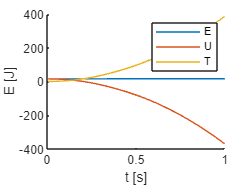

%% #3 plot
E=Tsim+Usim;
figure();
hold on;
plot(t,E);
plot(t,Usim);
plot(t,Tsim);
legend("E","U","T");
xlabel('t [s]');
ylabel('E [J]');

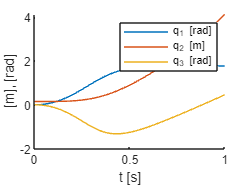


figure()
hold on;
plot(t,qsim(1,:));
plot(t,qsim(2,:));
plot(t,qsim(3,:));
xlabel('t [s]');
ylabel('[m], [rad]');
legend("q_1 [rad]","q_2 [m]","q_3 [rad]");

%% #5
qd=transpose(qd);
p=1/27;
kp=p/h^2

kp = 4.1152e+03

d=17/54;
kd=d/h

kd = 104.9383

KP=eye(3)*kp;
KD=eye(3)*kd;

tmax=3; 
step=round(tmax/h);

t=0:h:(step-1)*h;
qsim=zeros(3,step);
qsim(:,1)=q0;
qpsim=zeros(3,step);
qpsim(:,1)=[0;0;0];
usim=zeros(3,step);
usim(:,1)=[0;0;0];


for i=1:step-1
    M_i=subs(M,q, transpose(qsim(:,i)));
    C_i=subs(C,[q,qp],[ transpose(qsim(:,i)), transpose(qpsim(:,i))]); 
    ddq=M_i\(H*usim(:,i)-C_i);
    qpsim(:,i+1)=qpsim(:,i)+h*ddq; 
    qsim(:,i+1)=qsim(:,i)+h*qpsim(:,i);
    usim(:,i+1)=-KP*(qsim(:,i)-qd)-KD*qpsim(:,i); 
    if rem(i,10)==0
        fprintf("Remaining steps: %d\n", step - 1 - i)
    end
end

Remaining steps: 989
Remaining steps: 979
Remaining steps: 969
Remaining steps: 959
Remaining steps: 949
Remaining steps: 939
Remaining steps: 929
Remaining steps: 919
Remaining steps: 909
Remaining steps: 899
Remaining steps: 889
Remaining steps: 879
Remaining steps: 869
Remaining steps: 859
Remaining steps: 849
Remaining steps: 839
Remaining steps: 829
Remaining steps: 819
Remaining steps: 809
Remaining steps: 799
Remaining steps: 789
Remaining steps: 779
Remaining steps: 769
Remaining steps: 759
Remaining steps: 749
Remaining steps: 739
Remaining steps: 729
Remaining steps: 719
Remaining steps: 709
Remaining steps: 699
Remaining steps: 689
Remaining steps: 679
Remaining steps: 669
Remaining steps: 659
Remaining steps: 649
Remaining steps: 639
Remaining steps: 629
Remaining steps: 619
Remaining steps: 609
Remaining steps: 599
Remaining steps: 589
Remaining steps: 579
Remaining steps: 569
Remaining steps: 559
Remaining steps: 549
Remaining steps: 539
Remaining steps: 529
Remaining ste

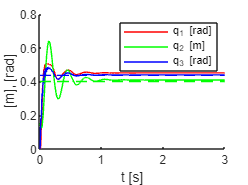

%% #5 plot
figure()
hold on;
plot(t,qsim(1,:),'r');
plot(t,qsim(2,:),'g');
plot(t,qsim(3,:),'b');
plot([0,tmax],[qd(1),qd(1)],'r--');
plot([0,tmax],[qd(2),qd(2)],'g--');
plot([0,tmax],[qd(3),qd(3)],'b--');
xlabel('t [s]');
ylabel('[m], [rad]');
legend("q_1 [rad]","q_2 [m]","q_3 [rad]");

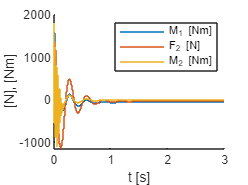


figure()
hold on;
stairs(t,usim(1,:));
stairs(t,usim(2,:));
stairs(t,usim(3,:));
xlabel('t [s]');
ylabel('[N], [Nm]');
legend("M_1 [Nm]","F_2 [N]","M_2 [Nm]");


% Joint-space error
e_jointPD=qsim(:,end)-qd

e_jointPD =     0.0146
    0.0090
    0.0029


% Workspace error
e_workPD=subs(r_TCPG(1:3),transpose(q),qsim(:,end))-r_TCPG_qd(1:3)

$$e\_workPD = \left(\begin{array}{c} -0.0145\\ -0.0200\\ 0 \end{array}\right)$$

%% #6
tmax=0.5; 
step=round(tmax/h);
t=0:h:(step-1)*h;

qsim=zeros(3,step);
qsim(:,1)=q0;
qpsim=zeros(3,step);
qpsim(:,1)=[0;0;0];
usim=zeros(3,step);
usim(:,1)=[0;0;0];
v=[0;0;0];

for i=1:step-1
    M_i=subs(M,q, transpose(qsim(:,i)));
    C_i=subs(C,[q,qp],[ transpose(qsim(:,i)), transpose(qpsim(:,i))]);
    ddq=M_i\(H*usim(:,i)-C_i);
    qpsim(:,i+1)=qpsim(:,i)+h*ddq;
    qsim(:,i+1)=qsim(:,i)+h*qpsim(:,i);
    v=qdpp-KP*(qsim(:,i)-qd)-KD*(qpsim(:,i)-qdp);
    usim(:,i+1)=H\(M_i*v+C_i);
    if rem(i,10)==0
        fprintf("Remaining steps: %d\n", step - 1 - i)
    end
end

Remaining steps: 156
Remaining steps: 146
Remaining steps: 136
Remaining steps: 126
Remaining steps: 116
Remaining steps: 106
Remaining steps: 96
Remaining steps: 86
Remaining steps: 76
Remaining steps: 66
Remaining steps: 56
Remaining steps: 46
Remaining steps: 36
Remaining steps: 26
Remaining steps: 16
Remaining steps: 6


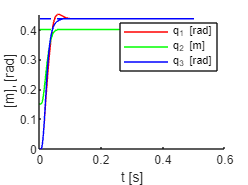

%% #6 plot
figure()
hold on;
plot(t,qsim(1,:),'r');
plot(t,qsim(2,:),'g');
plot(t,qsim(3,:),'b');
plot([0,tmax],[qd(1),qd(1)],'r--');
plot([0,tmax],[qd(2),qd(2)],'g--');
plot([0,tmax],[qd(3),qd(3)],'b--');
xlabel('t [s]');
ylabel('[m], [rad]');
legend("q_1 [rad]","q_2 [m]","q_3 [rad]");

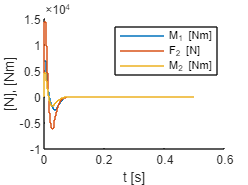


figure()
hold on;
stairs(t,usim(1,:));
stairs(t,usim(2,:));
stairs(t,usim(3,:));
xlabel('t [s]');
ylabel('[N], [Nm]');
legend("M_1 [Nm]","F_2 [N]","M_2 [Nm]");


% Joint-space error
e_joint=qsim(:,end)-qd

e_joint = 1.0e-15 *

   -0.1665
         0
    0.2220


% Workspace error
e_work=subs(r_TCPG(1:3),transpose(q),qsim(:,end))-r_TCPG_qd(1:3)

$$e\_work = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$